# CSE 685 Robot Control Theory - Term Project

**Professor Erkan Zergeroğlu**

Student: **Mahdi Amani Estalkhkuhi** - Student ID: **254213020402**

In this project, three controllers are applied to the given 3-DOF planar robot:

1. Computed-torque control 2. Robust control 3. Adaptive control

The controllers are first tested with the exact robot parameters. Then, parameter errors are added to see how robust each controller is.

Comments on the results are proveded at the end of this report.

**Stability proof are provided in "**`stabPro.mlx`** or **`stabPro.pdf`**".**

The Simulation has been conducted for 15 seconds.

clear;
close all;
clc;

## Robot model

The assigned system is a rigid 3-DOF planar robot. Its joint-space dynamics are

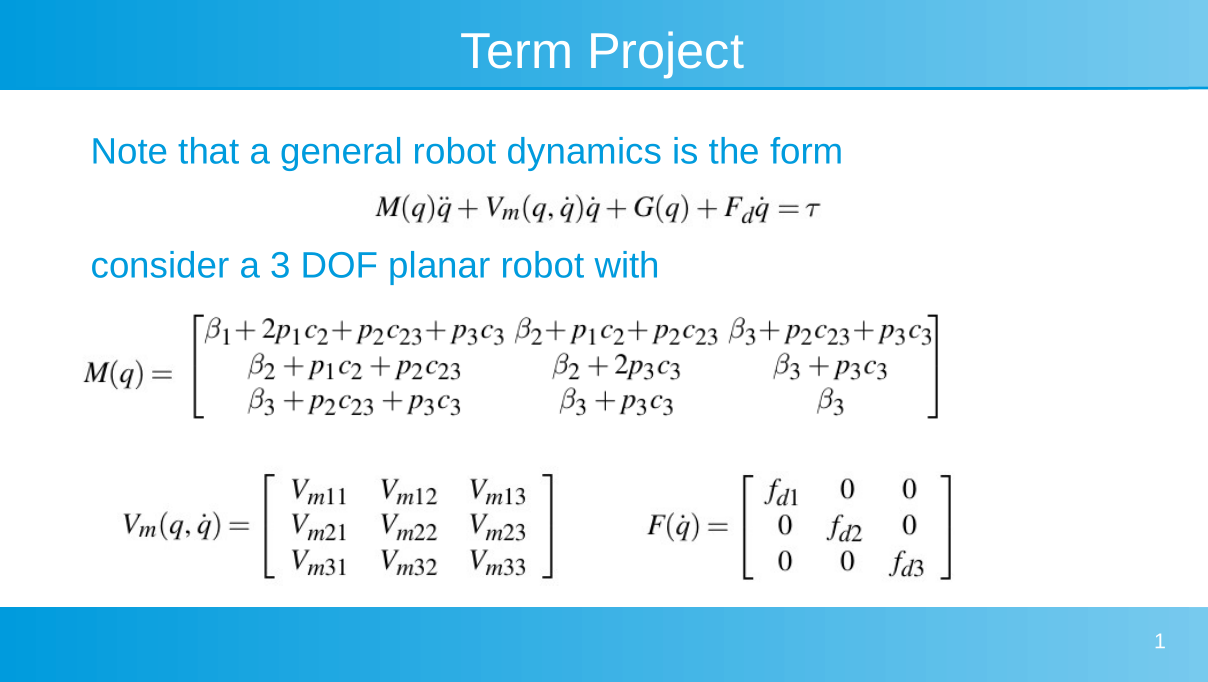

**** Note: Since the robot moves in a horizontal plane (planar), gravity does not produce joint torque in the given model. Therefore,**


$$G(q)=0.$$


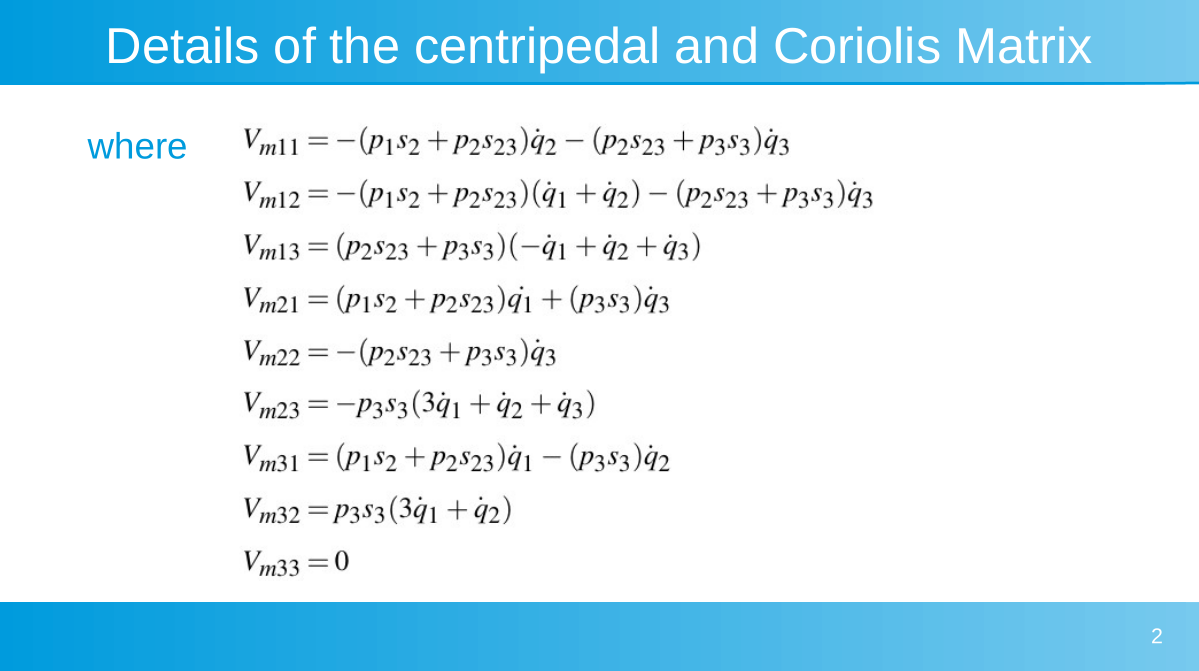

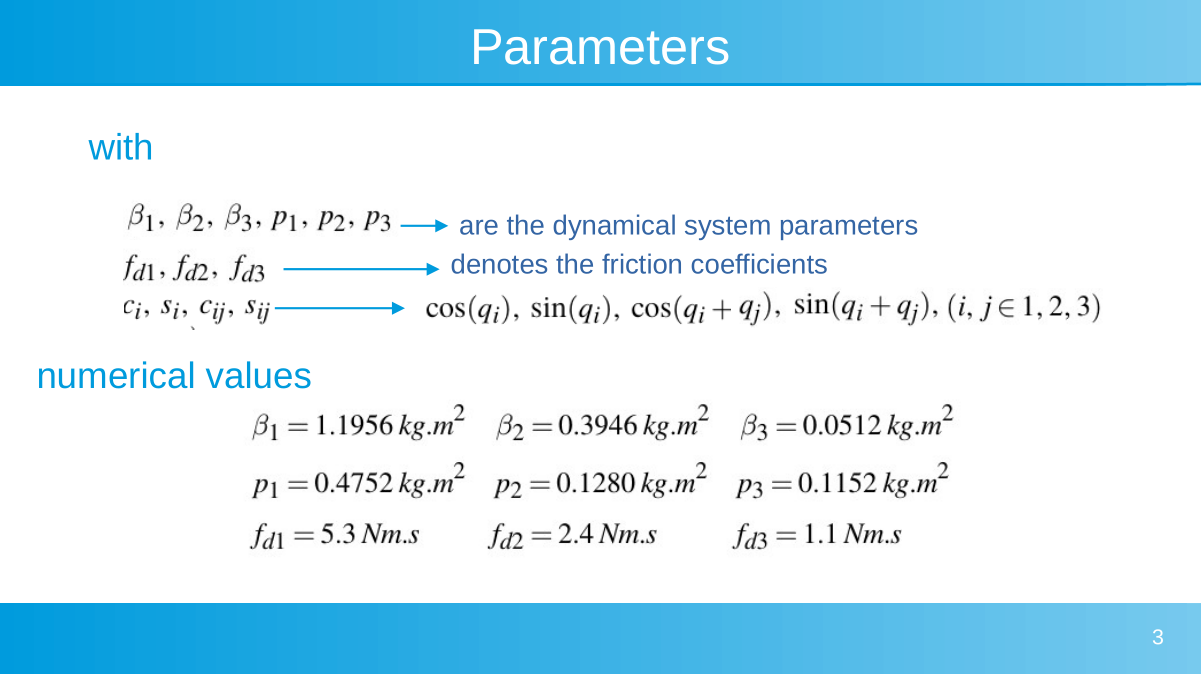

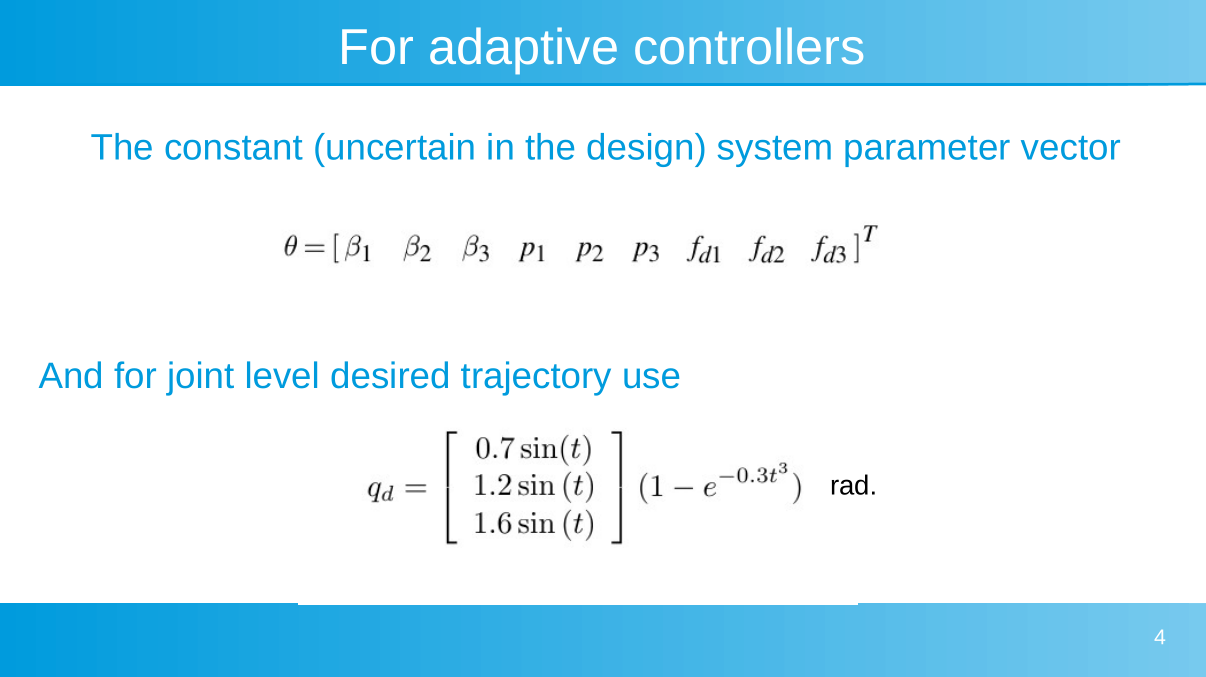

According to the project description, the numerical values given in the project statement are:

theta = [1.1956; 0.3946; 0.0512; 0.4752; 0.1280; 0.1152; ...
         5.3; 2.4; 1.1];

## Parameter uncertainty and simulation setup

Two cases are considered. In the first case, the controllers know the exact parameter vector. In the second case, the true robot remains unchanged, but **the model-based controllers** use the following **incorrect parameter values**.

Since the initial condition was not specified, the robot was initialized at $\(q(0)=[0.25,-0.20,0.15]^T\$ rad and $\(\dot q(0)=0\)$. The **nonzero position error** was intentionally selected to evaluate the transient tracking performance. The same initial condition was used for **all** controllers to ensure a **fair comparison**.

scale = [0.72; 1.25; 0.75; 1.28; 0.72; 1.25; 0.70; 1.30; 0.75]; % to create non-exact paramters
thetaWrong = theta.*scale;

tspan = [0 15];
x0 = [0.25; -0.20; 0.15; 0; 0; 0];
options = odeset("RelTol", 1e-6, "AbsTol", 1e-8);

## Desired trajectory

The desired joint trajectory is shown in the project description. The desired trajectory is prepared in function preapared `"desiredTrajectory.m"`

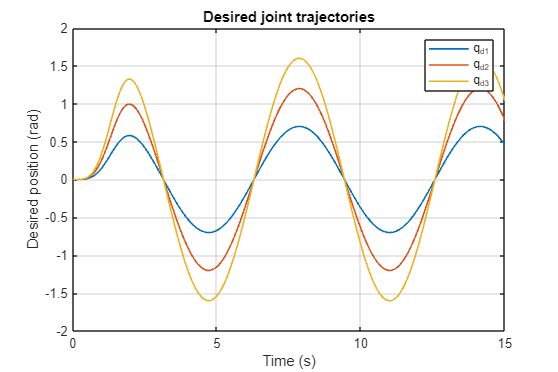

tPlot = linspace(0, 15, 500);
qDesired = zeros(length(tPlot), 3);

for i = 1:length(tPlot)
    qDesired(i,:) = desiredTrajectory(tPlot(i))';
end

figure("Color", "w","Position",0.75*[100 100 900 600]);
plot(tPlot, qDesired, "LineWidth", 1.2);
grid on;
xlabel("Time (s)");
ylabel("Desired position (rad)");
legend("q_{d1}", "q_{d2}", "q_{d3}");
title("Desired joint trajectories");

## Computed-torque controller

Define the position error as $e=q_d-q$. The computed-torque law is


$$\tau=\widehat M(q)
 \left(\ddot q_d+K_d\dot e+K_pe\right)
 +\widehat V_m(q,\dot q)\dot q+\widehat F_d\dot q.$$


If the model is **exact**, the nonlinear robot dynamics are cancelled and the tracking error behaves like a **second-order linear** system.


$$s^2+2\zeta\omega_n s+\omega_n^2=0,$$


The gains are selected as


$$K_p=\omega_n^2=\mathrm{diag}(64,64,64),\qquad
 K_d=2\zeta\omega_n=\mathrm{diag}(16,16,16).$$


Therefore, each nominal joint-error equation has the form


$$\ddot e_i+16\dot e_i+64e_i=0,$$


which corresponds to a critically damped second-order response with natural frequency $\omega_n=8$ rad/s and $\zeta=1$.

Kp = diag([64 64 64]);
Kd = diag([16 16 16]);

I have used theta (true values) for both model and plant according to description. Because in the computed torque, we assume all parameters are known.

ctExact = @(t,x) computedTorqueODE(t, x, theta, theta, Kp, Kd);
[tCT1, xCT1] = ode45(ctExact, tspan, x0, options);

In order to comparision the performance later with other methods, we can make a log from the non-exact model. 

ctWrong = @(t,x) computedTorqueODE(t, x, theta, thetaWrong, Kp, Kd);
[tCT2, xCT2] = ode45(ctWrong, tspan, x0, options);

## Robust controller

The filtered tracking error is


$$r=\dot e+\Lambda e.$$


A robust term is added to reduce the effect of parameter errors:


$$\tau=\widehat M\ddot q_r+\widehat V_m\dot q_r+\widehat F_d\dot q
 +K_r r+v_r,$$


where


$$v_r=\rho\,\mathrm{sat}(r/\phi),\qquad
 \rho=|Y|\overline{\theta}.$$


Here, $\overline{\theta}$ is the assumed componentwise upper bound on the parameter error.

The robust-controller parameters are


$$\Lambda=\mathrm{diag}(5,5,5),\qquad
 K_r=\mathrm{diag}(12,12,10).$$


The parameter-error bound and boundary-layer thickness are chosen as


$$\overline{\theta}=0.40|\theta|,\qquad \phi=0.20.$$


A larger $K_r$ increases damping of the filtered error. A smller boundary layer makes the saturation function closer to a sign function, but it can also make the torque less smooth.

LambdaRobust = diag([5 5 5]);
KrRobust = diag([12 12 10]);
thetaBound = 0.40*abs(theta);
phi = 0.20;

rbExact = @(t,x) robustODE(t, x, theta, theta, LambdaRobust, KrRobust, ...
    thetaBound, phi);
[tRB1, xRB1] = ode45(rbExact, tspan, x0, options);

rbWrong = @(t,x) robustODE(t, x, theta, thetaWrong, ...
    LambdaRobust, KrRobust, ...
    thetaBound, phi);
[tRB2, xRB2] = ode45(rbWrong, tspan, x0, options);

## Adaptive controller

The adaptive controller estimates the unknown robot parameters online:


$$\tau=Y(q,\dot q,\dot q_r,\ddot q_r)\widehat\theta+K_r r,$$



$$\dot{\widehat\theta}=\Gamma Y^T r.$$


The adaptive-controller gains are


$$\Lambda=\mathrm{diag}(5,5,5),\qquad
 K_r=\mathrm{diag}(12,12,10),$$



$$\Gamma=\mathrm{diag}(2,2,2,1,1,1,0.15,0.15,0.15).$$


The larger adaptation gains are used for the inertia and coupling parameters. 

Smaller gains are used for friction estimates to avoid very fast parameter changes. 

In the exact-model test, the initial estimate is $70\%$ of the true vector. 

In the uncertainty test, it starts from the same incorrect vector used by the other model-based controllers.

LambdaAdaptive = diag([5 5 5]);
KrAdaptive = diag([12 12 10]);
Gamma = diag([2 2 2 1 1 1 0.15 0.15 0.15]);

thetaHat0 = 0.70*theta;
x0Adaptive = [x0; thetaHat0];

adExact = @(t,x) adaptiveODE(t, x, theta, ...
    LambdaAdaptive, KrAdaptive, Gamma, theta);
[tAD1, xAD1] = ode45(adExact, tspan, x0Adaptive, options);


The adaptive controller starts with the same incorrect parameters used

by the other controllers in the uncertain-model test.

x0AdaptiveWrong = [x0; thetaWrong];
adWrong = @(t,x) adaptiveODE(t, x, theta, ...
    LambdaAdaptive, KrAdaptive, Gamma, theta);
[tAD2, xAD2] = ode45(adWrong, tspan, x0AdaptiveWrong, options);

## Tracking results with parameter errors

This is the main comparison. All three controllers use the **same initial condition** and the **same true robot**.

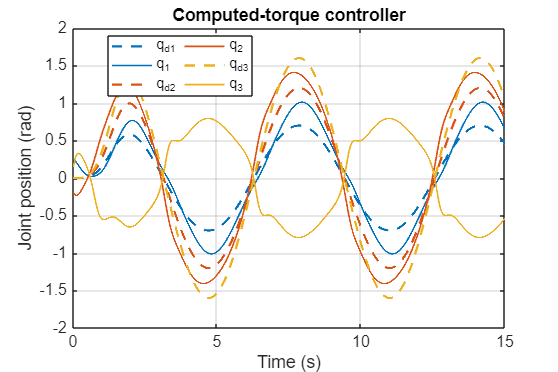

[eCT, rCT, tauCT] = simulationSignals(tCT2, xCT2, 1, thetaWrong, ...
    Kp, Kd, LambdaRobust, KrRobust, thetaBound, phi);
[eRB, rRB, tauRB] = simulationSignals(tRB2, xRB2, 2, thetaWrong, ...
    Kp, Kd, LambdaRobust, KrRobust, thetaBound, phi);
[eAD, rAD, tauAD] = simulationSignals(tAD2, xAD2, 3, thetaWrong, ...
    Kp, Kd, LambdaAdaptive, KrAdaptive, thetaBound, phi);

% Computed-torque tracking
figure("Color","w","Position",0.75*[100 100 900 600]);
plotTracking(tCT2, xCT2(:,1:3), ...
    "Computed-torque controller");

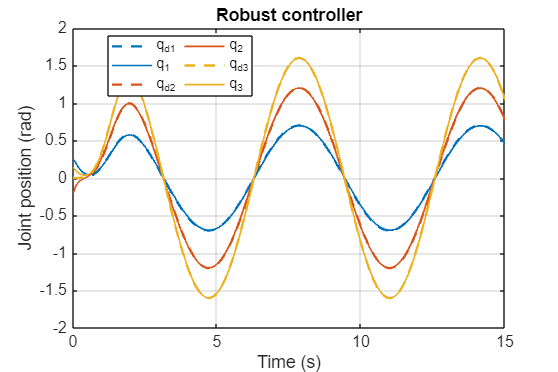


% Robust-control tracking
figure("Color","w","Position",0.75*[100 100 900 600]);
plotTracking(tRB2, xRB2(:,1:3), ...
    "Robust controller");

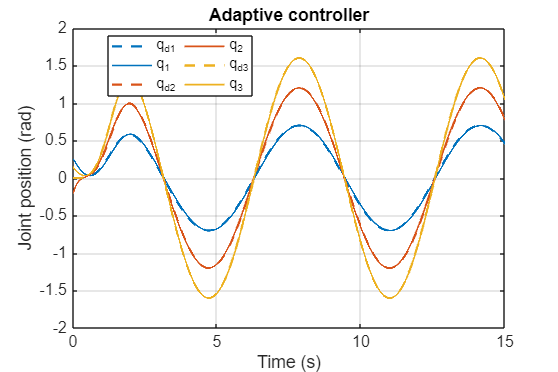


% Adaptive-control tracking
figure("Color","w","Position",0.75*[100 100 900 600]);
plotTracking(tAD2, xAD2(:,1:3), ...
    "Adaptive controller");

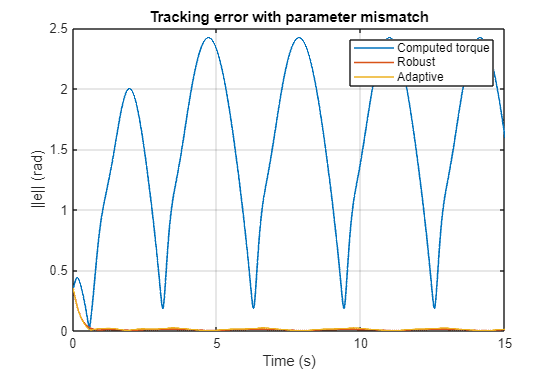


figure("Color", "w","Position",0.75*[100 100 900 600]);
plot(tCT2, sqrt(sum(eCT.^2,2)), "LineWidth", 1.2);
hold on;
plot(tRB2, sqrt(sum(eRB.^2,2)), "LineWidth", 1.2);
plot(tAD2, sqrt(sum(eAD.^2,2)), "LineWidth", 1.2);
grid on;
xlabel("Time (s)");
ylabel("||e|| (rad)");
legend("Computed torque", "Robust", "Adaptive");
title("Tracking error with parameter mismatch");

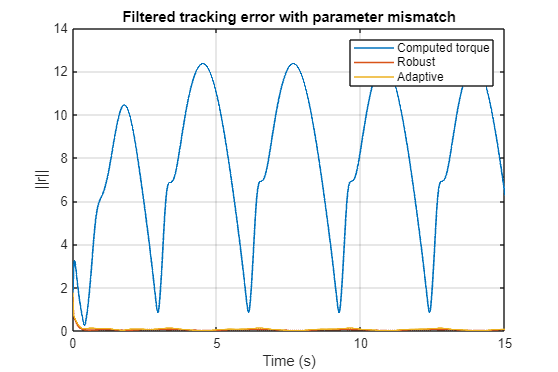


figure("Color", "w","Position",0.75*[100 100 900 600]);
plot(tCT2, sqrt(sum(rCT.^2,2)), "LineWidth", 1.2);
hold on;
plot(tRB2, sqrt(sum(rRB.^2,2)), "LineWidth", 1.2);
plot(tAD2, sqrt(sum(rAD.^2,2)), "LineWidth", 1.2);
grid on;
xlabel("Time (s)");
ylabel("||r||");
legend("Computed torque", "Robust", "Adaptive");
title("Filtered tracking error with parameter mismatch");

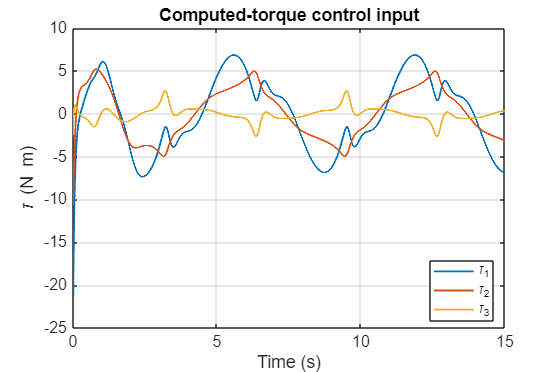


% Computed-torque control input
figure("Color","w","Position",0.75*[100 100 900 600]);

plot(tCT2, tauCT(:,1), "LineWidth", 1.4);
hold on;
plot(tCT2, tauCT(:,2), "LineWidth", 1.4);
plot(tCT2, tauCT(:,3), "LineWidth", 1.4);

grid on;
box on;
xlabel("Time (s)");
ylabel("\tau (N m)");
title("Computed-torque control input");
legend("\tau_1", "\tau_2", "\tau_3", "Location","best");
set(gca,"FontSize",12);

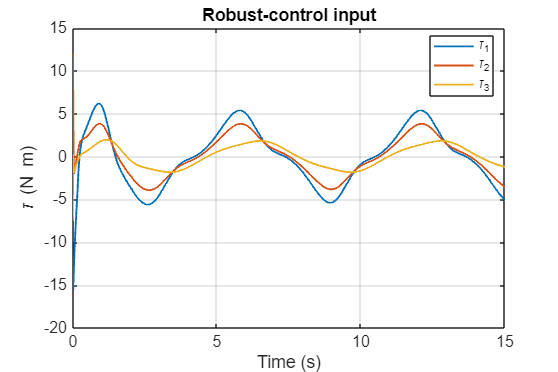



% Robust-control input
figure("Color","w","Position",0.75*[100 100 900 600]);

plot(tRB2, tauRB(:,1), "LineWidth", 1.4);
hold on;
plot(tRB2, tauRB(:,2), "LineWidth", 1.4);
plot(tRB2, tauRB(:,3), "LineWidth", 1.4);

grid on;
box on;
xlabel("Time (s)");
ylabel("\tau (N m)");
title("Robust-control input");
legend("\tau_1", "\tau_2", "\tau_3", "Location","best");
set(gca,"FontSize",12);

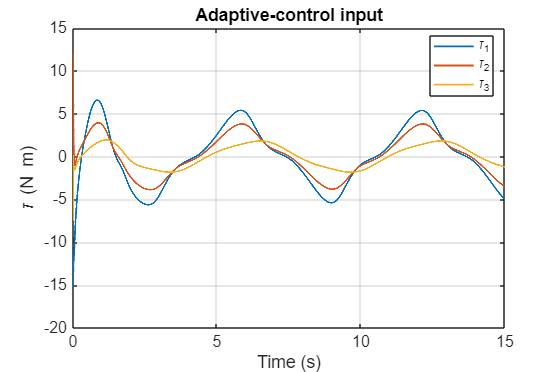



% Adaptive-control input
figure("Color","w","Position",0.75*[100 100 900 600]);

plot(tAD2, tauAD(:,1), "LineWidth", 1.4);
hold on;
plot(tAD2, tauAD(:,2), "LineWidth", 1.4);
plot(tAD2, tauAD(:,3), "LineWidth", 1.4);

grid on;
box on;
xlabel("Time (s)");
ylabel("\tau (N m)");
title("Adaptive-control input");
legend("\tau_1", "\tau_2", "\tau_3", "Location","best");
set(gca,"FontSize",12);

## Simple numerical comparison

**RMS** error is calculated for each controller. A smaller value means better tracking over the complete simulation. Both the **exact-model** and **uncertain-model** cases are included.

[eCTExact, ~, ~] = simulationSignals(tCT1, xCT1, 1, theta, ...
    Kp, Kd, LambdaRobust, KrRobust, thetaBound, phi);
[eRBExact, ~, ~] = simulationSignals(tRB1, xRB1, 2, theta,  ...
    Kp, Kd, LambdaRobust, KrRobust, thetaBound,phi);
[eADExact, ~, ~] = simulationSignals(tAD1, xAD1, 3, theta, ...
    Kp, Kd, LambdaAdaptive, KrAdaptive, thetaBound, phi);

rmsCTExact = sqrt(trapz(tCT1, sum(eCTExact.^2,2))/(tCT1(end)-tCT1(1))) ;
rmsRBExact = sqrt(trapz(tRB1, sum(eRBExact.^2,2))/(tRB1(end)-tRB1(1)));
rmsADExact =sqrt(trapz(tAD1, sum(eADExact.^2,2))/(tAD1(end)-tAD1(1)));

rmsCT = sqrt(trapz(tCT2, sum(eCT.^2,2))/(tCT2(end)-tCT2(1)));
rmsRB = sqrt(trapz(tRB2, sum(eRB.^2,2))/(tRB2(end)-tRB2(1)));
rmsAD = sqrt(trapz(tAD2, sum(eAD.^2,2))/(tAD2(end)-tAD2(1)));

Controller = ["Computed torque"; "Robust"; "Adaptive"];
ExactModel = [rmsCTExact; rmsRBExact; rmsADExact];
ParameterMismatch = [rmsCT; rmsRB; rmsAD];
results = table(Controller, ExactModel, ParameterMismatch);
disp(results);

       Controller        ExactModel    ParameterMismatch
    _________________    __________    _________________

    "Computed torque"     0.036085           1.6789     
    "Robust"              0.032966         0.034343     
    "Adaptive"            0.035935          0.03574     



## Comments on the results

In the exact-model test, all three controllers follow the desired trajectory. Computed torque performs well because the model used by the controller is the same as the real robot model.

### computed-torque

After parameter errors are added, the computed-torque error becomes much larger. Because this controller depends directly on cancellation of the nonlinear robot dynamics. If the model is wrong, the cancellation is also wrong.

### robust controller

The robust controller gives a much smaller error in the uncertain case. The saturation term acts against the bounded effect of the parameter errors. Its disadvantage is that it can require a stronger control input, especially near the beginning of the motion. The boundary layer makes the input smoother than a pure sign function, but it can leave a small tracking error close to the surface.

### adaptive controller

The adaptive controller also keeps the tracking error small. Instead of using a fixed extra term, it changes the estimated robot parameters while the robot is moving. The estimates do not all have to reach their exact values for good tracking. For this trajectory, the main result is that the tracking error decreases and remains bounded.

From these simulations, the robust and adaptive controllers are more suitable when the robot parameters are uncertain. The robust controller is simpler to tune, while the adaptive controller gives useful online parameter adjustment but needs more calculations.

## Adaptive parameter estimates

Tracking can converge even when every estimated parameter does not converge exactly to its true value. Exact parameter convergence also depends on persistent excitation.

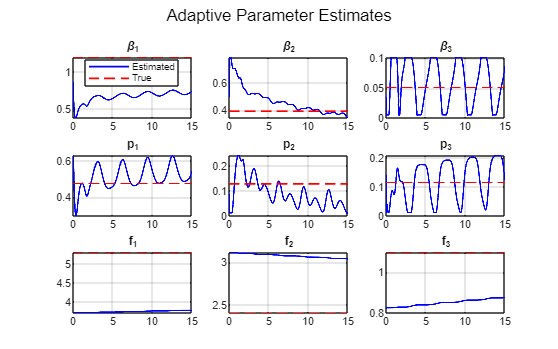

figure("Color","w","Position",0.65*[50 50 1200 750]);

names = ["\beta_1" "\beta_2" "\beta_3" ...
         "p_1" "p_2" "p_3" ...
         "f_1" "f_2" "f_3"];

for i = 1:9
    subplot(3,3,i);

    plot(tAD2,xAD2(:,6+i),"b","LineWidth",1.3);
    hold on;
    plot(tAD2,theta(i)*ones(size(tAD2)),"r--","LineWidth",1.3);

    grid on;
    title(names(i));
    xlim([0 15]);

    if i == 1
        legend("Estimated","True","Location","best");
    end
end

sgtitle("Adaptive Parameter Estimates");

## References:

- Lectune notes of the course by Prof. Erkan

- Theory of Robot Control, C. C. De Witt

- Robot Manipulator Control Lewis

## Contact

email: m.amani2026@gtu.edu.tr

Website: [https://sites.google.com/view/maekuhi](https://sites.google.com/view/maekuhi)